configuration = 'cl1_angle_down';
% cl1_no_angle_down
% cl1_no_angle_up

% cl2_no_angle_down
% cl2_no_angle_up

% cl1_angle_down
% cl1_angle_up

% cl2_angle_down
% cl2_angle_up

% pickup



[data,input_data_pos, input_data_vel, current_file, reverse] = readData(configuration);



if strcmp(configuration, 'pickup')
    fs = 50; 
    total_time = 9.7551; 
    t1 = 0.5365;
    t2 = 3.506;
    t3 = 5.225;
    t4 = 9.7551;
    t_pickup = 0:1/fs:total_time;
    path_pickup = zeros(size(t_pickup));
    idx1 = t_pickup <= t1;
    path_pickup(idx1) = 50;
    idx2 = t_pickup > t1 & t_pickup <= t2;
    path_pickup(idx2) = 50 * (1 - (t_pickup(idx2) - t1) / (t2 - t1));
    idx3 = t_pickup > t2 & t_pickup <= t3;
    path_pickup(idx3) = 0;
    idx4 = t_pickup > t3 & t_pickup <= t4;
    path_pickup(idx4) = 80 * (t_pickup(idx4) - t3) / (t4 - t3);
    input_data_pos = path/100;
    input_data_vel = diff(input_data_pos)/(1/fs);
    end




freq = 50;
time_step = 1/freq;

R_x = 0.04;  %afstand motor as tot bewegingslijn
R_z = 0.1;


% Extract time (1st column) and x position (4th column)
time =  data(:,1) - data(1,1);
x_position = data(:, 4);
x_velocity = data(:,5);
angle = smoothdata(data(:, 15));
z_position = data(:,8)*100;
first_zero_index = find(x_position <0.01 & x_position >-0.01, 1, 'first');
time_shift = time(first_zero_index)

time_shift = 4.9295

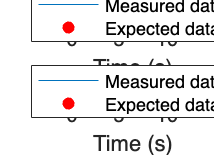

[~,collision_index] = max(x_position);
pickup_shift = 0;
pickup_shift_2 = 0;
if strcmp(configuration, 'pickup')
    pickup_shift =time_shift;
    pickup_shift_2 = 1;
end



input_time = 1:length(input_data_pos);
current_time = 1:length(current_file);
input_position = input_data_pos(1,:);
[~,collision_index_input] = max(input_position);


input_velocity = input_data_vel(1,:);

current_amp = current_file(:,1)/1000;
load_angle = current_file(:,2)/1000;

figure;
subplot(2,1,1)
plot(time, x_position);
xlabel('Time (s)');
ylabel('X Position (cm)');
hold on 
scatter(input_time/freq +time_shift - pickup_shift, input_position*100, 2, 'r', 'filled');
hold off
%title('X Position vs Time motor');
legend('Measured data', 'Expected data', 'Location', 'best');
xlim([time(1),time(end)])

subplot(2,1,2)
plot(time(2000:end) , (x_velocity(2000:end)));
xlabel('Time (s)');
ylabel('X Velocity (cm/s)');
hold on 
scatter(input_time(1+pickup_shift_2:end)/freq + time_shift -pickup_shift , input_velocity*100, 2, 'r', 'filled');
hold off
%title('X Velocity vs Time motor');
legend('Measured data', 'Expected data', 'Location', 'best');
xlim([time(1),time(end)])

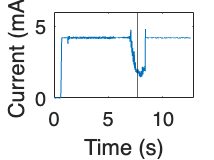





figure
plot(current_time/freq , current_amp)
xlabel('Time (s)')
ylabel('Current (mA)')
xlim([time(1),time(end)])
xline(current_time(collision_index_input)/freq+time_shift)

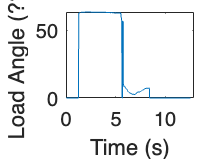


figure
plot(current_time/freq  , load_angle)
xlabel('Time (s)')
ylabel('Load Angle (???)')
xlim([time(1),time(end)])

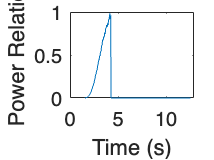



% P = 2*pi*T*n / 60 ~= 2*pi*I*cos(phi) * v /(2*pi r) = (I*cos(phi)*v/(r*60))
current = current_amp.*cos(load_angle);
index_min = min(length(input_velocity),length(current));
power = current(length(current)-index_min+1:end)'.*input_velocity(length(input_velocity)-index_min+1:end)/(R_x*60);
current_time = current_time(length(current_time)-index_min+1:end);
energy= cumtrapz(power);

figure 
plot(current_time/freq,power)
xlabel("Time (s)")
ylabel(" Power Relation")
xlim([time(1),time(end)])

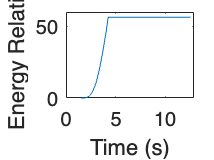


figure 
plot(current_time/freq ,energy)
xlabel("Time (s)")
ylabel(" Energy Relation")
xlim([time(1),time(end)])



figure
plot(time, (angle));
xlabel('Time (s)');
ylabel('Object Angle (deg)');
%title('angel vs time');
hold on 
xline(time(collision_index))
start_angle = min(angle(1:collision_index-1))


start_angle =

  0×1 empty double column vector



new_angle = max(angle(collision_index:end))

new_angle = -48.2031


gain = abs(new_angle/start_angle)


gain =

  1×0 empty double row vector



if reverse == true
    new_angle =max(angle(collision_index+1000:end))
end

new_angle = -48.2031

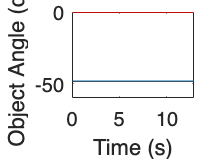

yline(0,'r')

yline(start_angle)
yline(new_angle)
hold off

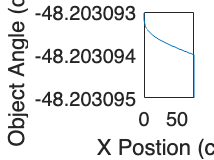




figure
plot(x_position(first_zero_index:end), angle(first_zero_index:end));
xlabel('X Postion (cm)');
ylabel('Object Angle (deg)');

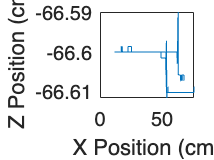

%title('angle vs x-position motor');


if strcmp(configuration, 'pickup')
figure
plot(x_position, -z_position);
xlabel('X Position (cm)');
ylabel('Z position (cm)');
%title('Object position');
xlim([-5;85])
ylim([-155;-100])
else 
figure
plot(smoothdata(x_position +sin(angle)), -z_position.*cos(angle*pi/180));
xlabel('X Position (cm)');
ylabel('Z Position (cm)');
%title('Object position');
end